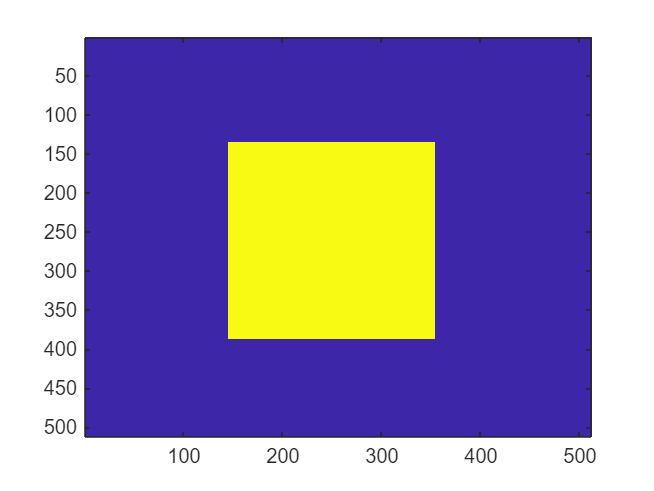

clear
addpath("Codes/Matlab");

c0=0;c1=0;c2=0;c3=0;
A = [ 1      c0          c1;
      c2    1+c0*c2    c1*c2;
      c3 c0*c1*c2*c3 1+c1*c3];
M = 256;

f = 3.6;
d_0 = 0.5;

alpha = 0.04;
beta = 0.08;

I = imread("Images/article/1.png");
W = imread("Images/article/w.png");
Mask = imread("Images/article/m.png");

[a,b,c] = size(I);



[F_I,B_I] = separation(I,Mask);
[F_W,B_W] = separation(W,Mask);

F_W_arnold = arnold(F_W,A,M);
B_W_arnold = arnold(B_W,A,M);
% Arnaque 0 : M = 256 non 512

F_W_logistic = logistic_map(F_W_arnold,Mask,d_0,f,false);
B_W_logistic = logistic_map(B_W_arnold,1-Mask,d_0,f,false);

F_final = apply_haar(F_I, F_W_logistic, alpha);
B_final = apply_haar(B_I, B_W_logistic, beta);

I_prime = fusion(F_final,B_final,Mask);
% Arnaque 1 : Je n'ai pas une image uint8 à la fin du tatouage
% cause : mes données ne sont pas en int

imagesc(uint8(Mask))

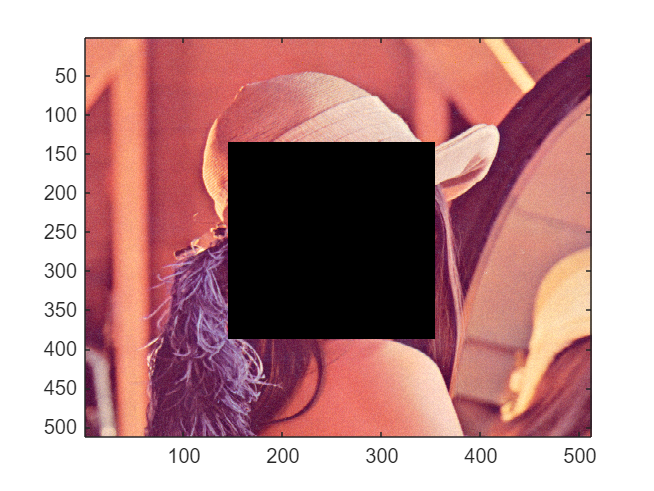

imagesc(uint8(B_final))

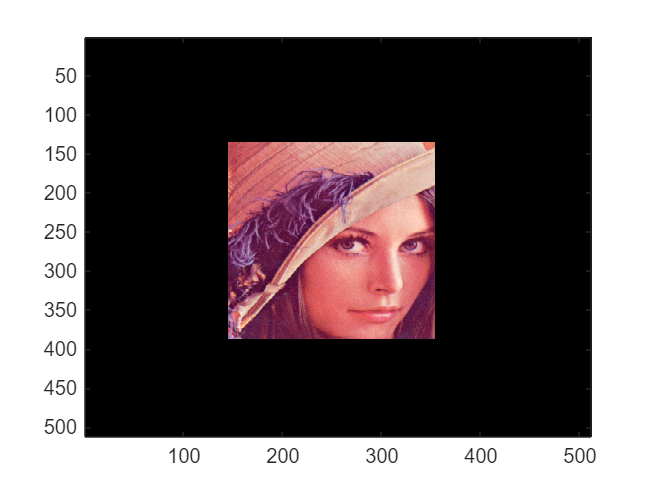

imagesc(uint8(F_final))

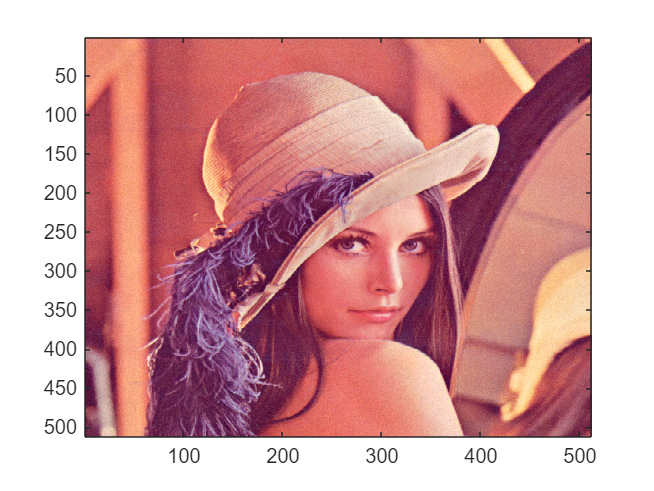

imagesc(uint8(I_prime))

% -----------------------------------

[I_mean,I_median,I_noise,I_rotate,I_crop,I_jpeg,I_shear] = attacks(I_prime);
%I_prime_prime = I_mean;
I_prime_prime = round(I_prime);

[F_Iw,B_Iw] = separation(I_prime_prime,Mask);
% Arnaque 2 : Mais on s'en fout de l'arnaque 1 car au final je n'utilise
% pas cette séparation dans la suite
% cause : F_final et F_Iw ne sont pas =, leur différence est sur la "ligne
% du masque"
%F_Iw = F_final;
%B_Iw = B_final;

F_W_logistic_recover = reverse_haar(F_I, F_Iw, alpha);
B_W_logistic_recover = reverse_haar(B_I, B_Iw, beta);
% Arnaque 3 : J'utilise F_W_logistic pour retrouver F_W_logistic...
% cause : Car on a besoin des HL LH HH qu'on a pas sinon....


F_W_arnold_recover = logistic_map(F_W_logistic_recover,Mask,d_0,f,true);
B_W_arnold_recover = logistic_map(B_W_logistic_recover,1-Mask,d_0,f,true);

F_W_recover = arnold(F_W_arnold_recover,inv(A),M);
B_W_recover = arnold(B_W_arnold_recover,inv(A),M);

W_prime = uint8(round(fusion(F_W_recover,B_W_recover,Mask)));

imagesc(uint8(I_prime));

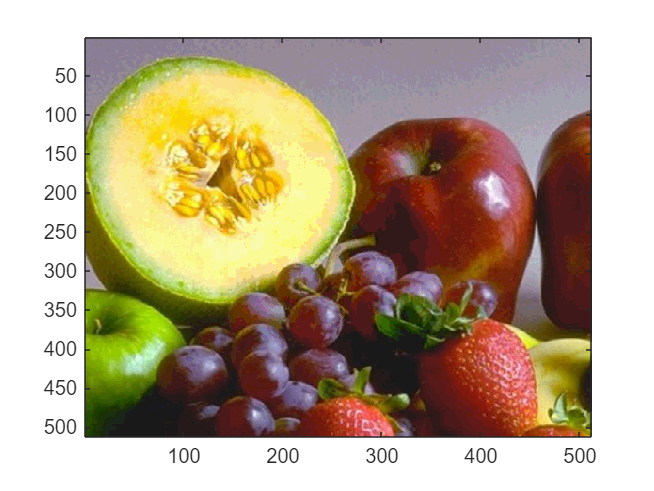

imagesc(uint8(W_prime));


ssim(W_prime,W)

ans = 0.9754